# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'pdf';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
. Processing the test case #1...


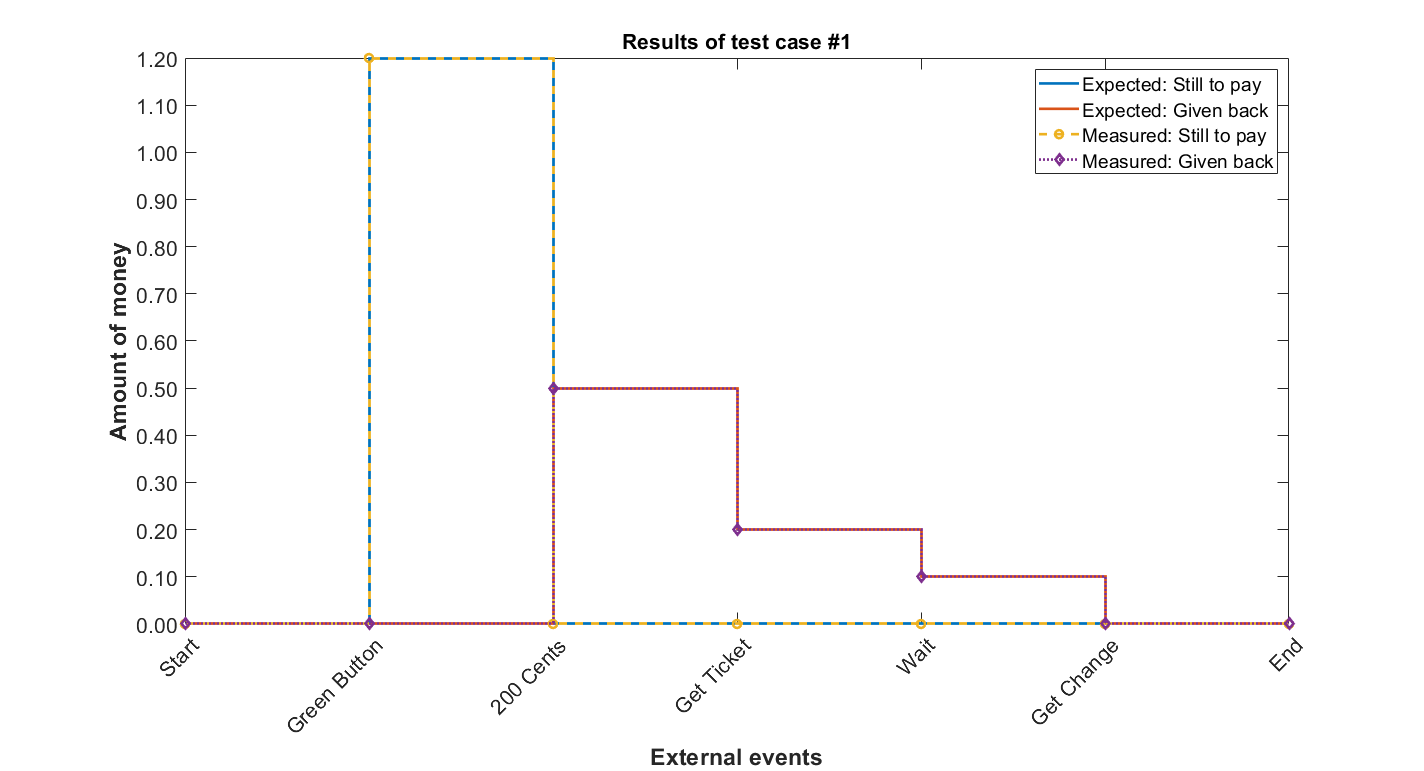


[Terse] Diagnostic logged (2021-11-11 15:45:54):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_b9807475-596d-4d28-ba66-82a865ba270b.fig
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_b9807475-596d-4d28-ba66-82a865ba270b.png
. Processing the test case #2...


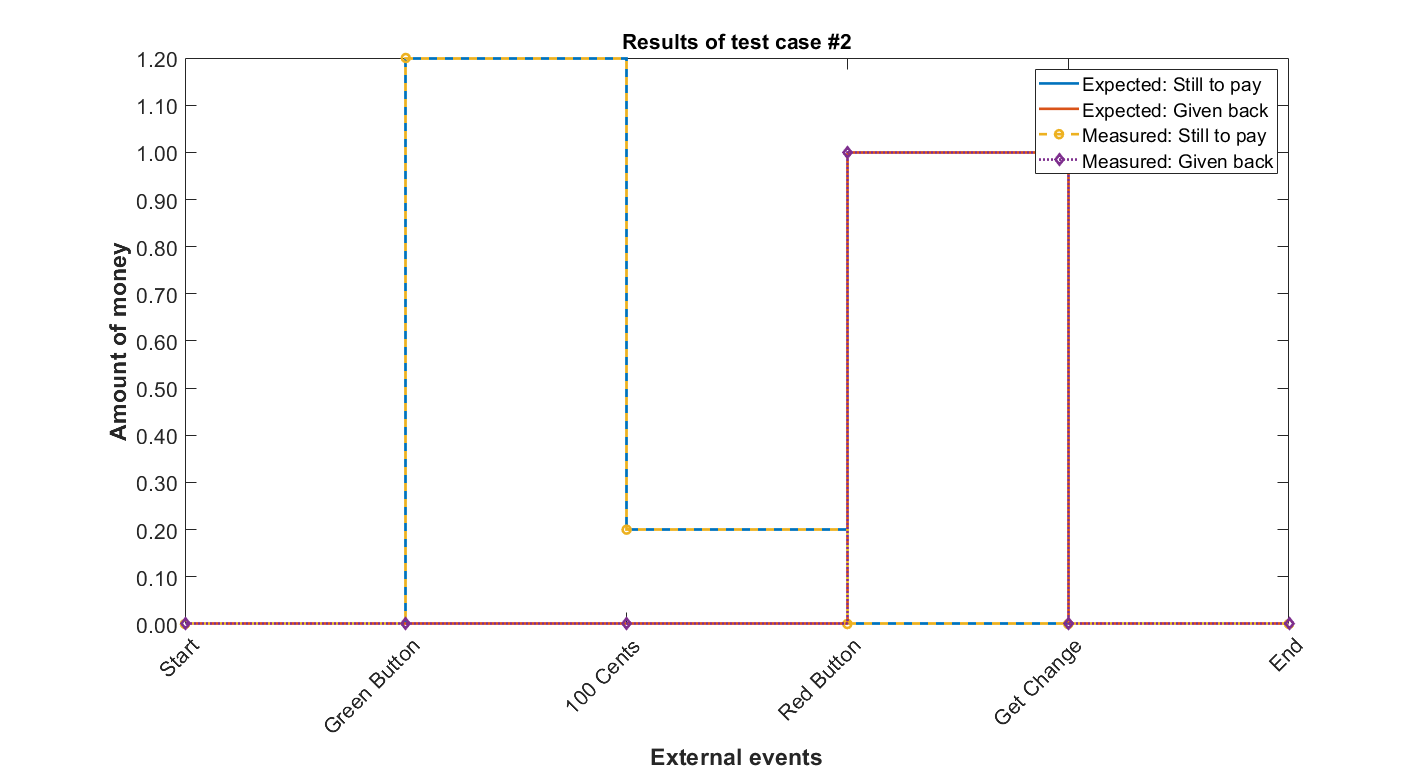


[Terse] Diagnostic logged (2021-11-11 15:46:17):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_f50b566f-160d-48a3-ab0c-285aad3c9570.fig
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_f50b566f-160d-48a3-ab0c-285aad3c9570.png
. Processing the test case #3...


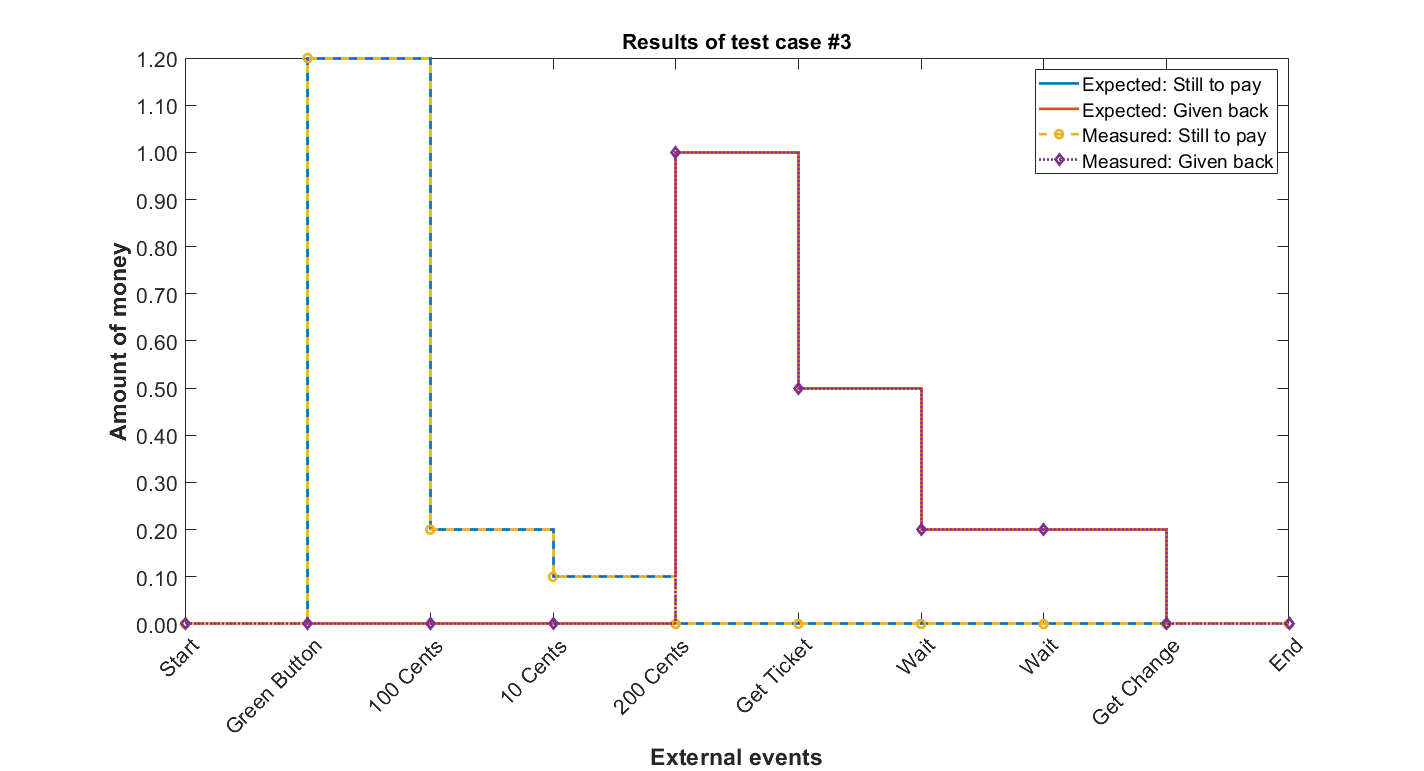


[Terse] Diagnostic logged (2021-11-11 15:46:46):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_431b25e1-6205-4331-a19f-651669ffd0ca.fig
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_431b25e1-6205-4331-a19f-651669ffd0ca.png
. Processing the test case #4...


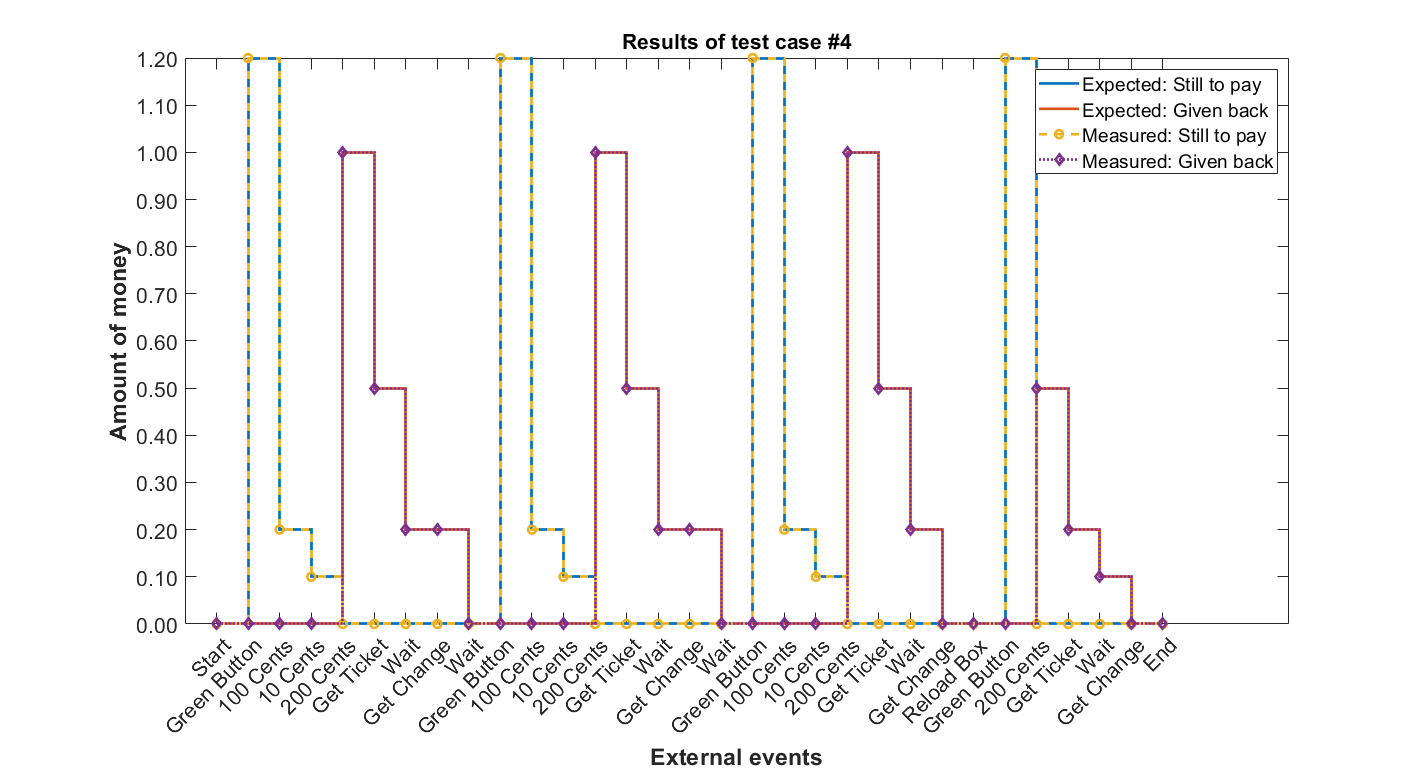


[Terse] Diagnostic logged (2021-11-11 15:48:16):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_33c9ab46-afe7-47b7-91d6-79f675252dd2.fig
--> C:\Users\sebas\AppData\Local\Temp\dfc9c9d2-09e3-49ef-b6b9-7bd1e23b55e2\Figure_33c9ab46-afe7-47b7-91d6-79f675252dd2.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.
    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.pdf
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp22b5fefb_d557_44b6_9f0c_9a72ee8cb20e\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false         26.04     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        21.978     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    true      false       false         29.24     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    true      false       false        89.593     {1×1 struct}

